format long

rho = 10;
g = 9.8;
L = 2;
JE = 2000;
f = @(x,z,w) (w);
g = @(x,z,w) ( (rho*g/JE)*((1 + w^2)^(3/2))*( x*(x-L/2)  + (L^2)/2 )  );

z0 = 0;
w0 = 0;
a = 0;
b = L;
h = 0.001;

[zrk2 , wrk2] = rk2_sist(f,g,a,b,z0,w0,h);

solu1 = zrk2;

[zeuler , weuler] = euler(f,g,a,b,z0,w0,h);

solu2 = zeuler;

solu = [solu2 , solu1]

solu =                    0                   0
                   0   0.000000049000000
   0.000000098000000   0.000000195951050
   0.000000293951050   0.000000440804302
   0.000000587804302   0.000000783511008
   0.000000979511008   0.000001224022520
   0.000001469022520   0.000001762290293
   0.000002056290293   0.000002398265880
   0.000002741265880   0.000003131900936
   0.000003523900936   0.000003963147218




rho = 10;
g = 9.8;
L = 2;
JE = 2000;

f=@(t,x)[x(2); rho*g/JE*(1 + x(2).^(2)).^(3/2).*(t.*(t-L/2)+ L^2/2)];
x0=0; xf=L; y0=[0 0]; N=100;
[x,y]=ode45(f,[x0 xf],y0)

x =                    0
   0.000512629883982
   0.001025259767963
   0.001537889651945
   0.002050519535926
   0.004613668955834
   0.007176818375742
   0.009739967795649
   0.012303117215557
   0.025118864315096


y =                    0                   0
   0.000000012875581   0.000050231292554
   0.000000051497925   0.000100449722009
   0.000000115860444   0.000150655301947
   0.000000205956552   0.000200848045949
   0.000001042211006   0.000451619702204
   0.000002520821677   0.000702072496850
   0.000004640973452   0.000952208126847
   0.000007401855563   0.001202028288804
   0.000030789148510   0.002446456436043


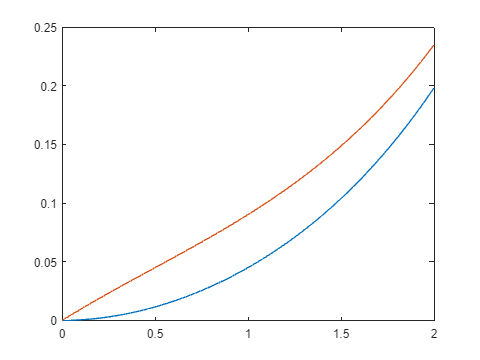

plot(x,y)

function [xeuler, yeuler] = euler(f,g,a,b,x0,y0,h)
    tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        x1(i+1,1) = x0 + h*k1x;
        y1(i+1,1) = y0 + h*k1y;
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xeuler = x1;
    yeuler = y1;
end

function [xrk2, yrk2] = rk2_sist(f,g,a,b,x0,y0,h)
    tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        k2x = f(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        k2y = g(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        x1(i+1,1) = x0 + h*(0.5*k1x + 0.5*k2x);
        y1(i+1,1) = y0 + h*(0.5*k1y + 0.5*k2y);
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xrk2 = x1;
    yrk2 = y1;
end
